%1. 計算以下圖形的 PageRank 向量，其阻尼常數 p=0, p=0.15, p=0.5 和 p=1 分別討論。
%根據不同計算結果將最後計算完的PageRank向量存在:
%PageRank_vec_0、PageRank_vec_0_15、PageRank_vec_0_5、PageRank_vec_1


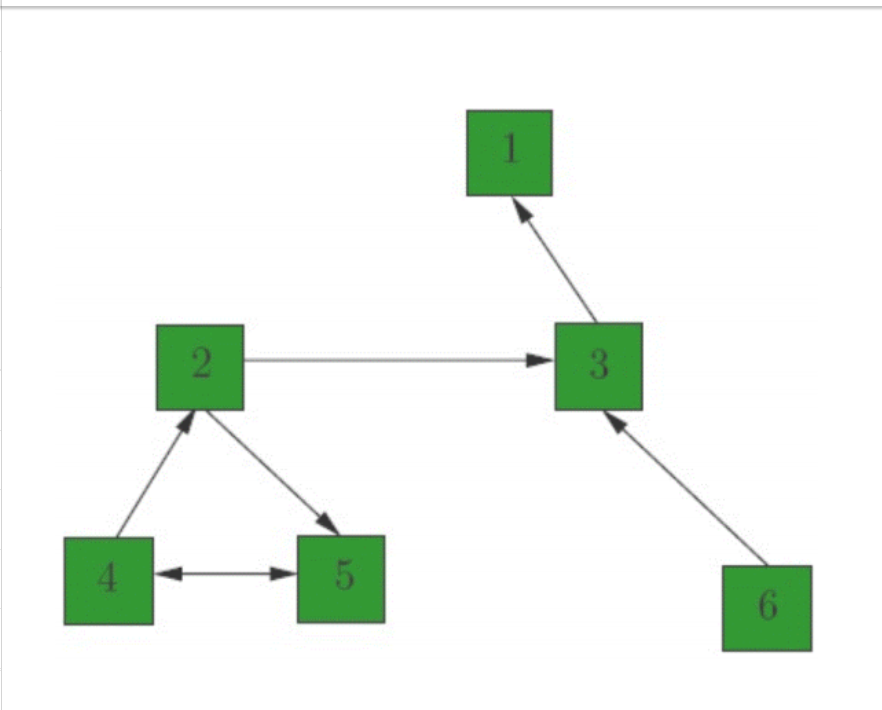

A=   [1/6 0   1 0   0    0;
      1/6 0   0 0.5 0    0;
      1/6 0.5 0 0   0    1;
      1/6 0   0 0   1    0;
      1/6 0.5 0 0.5 0    0;
      1/6 0   0 0   0    0;];
b=ones(6)/6;

p=0;
mat0=(1-p)*A+p*b;
[eigvec, eigval] = eig(mat0);
PageRank_vec_0=eigvec(:,1)/sum(eigvec(:,1))

p=0.15;
mat1=(1-p)*A+p*b;
[eigvec, eigval] = eig(mat1);
PageRank_vec_0_15=eigvec(:,1)/sum(eigvec(:,1))

p=0.5;
mat2=(1-p)*A+p*b;
[eigvec, eigval] = eig(mat2);
PageRank_vec_0_5=eigvec(:,1)/sum(eigvec(:,1))

p=1;
mat3=(1-p)*A+p*b;
[eigvec, eigval] = eig(mat3);
PageRank_vec_1=eigvec(:,6)/sum(eigvec(:,6))

%2. 計算以下具方向性圖形的 PageRank 向量，阻尼常數為 p=0.15。
%PageRank 向量結果存在 PageRank_vec 中
%闡釋每個節點的進來連接的數目與它的 Rank 之間的關係。

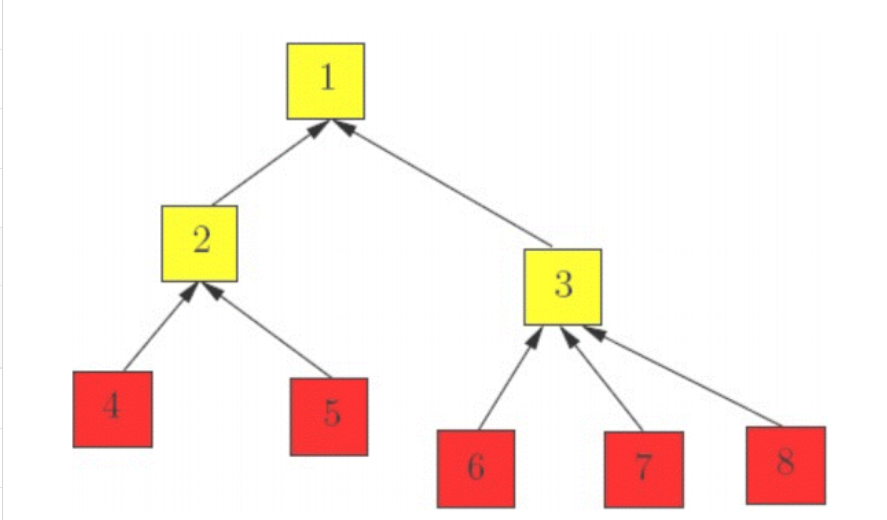

a=[1/8 1 1 0 0 0 0 0;
   1/8 0 0 1 1 0 0 0;
   1/8 0 0 0 0 1 1 1;
   1/8 0 0 0 0 0 0 0;
   1/8 0 0 0 0 0 0 0;
   1/8 0 0 0 0 0 0 0;
   1/8 0 0 0 0 0 0 0;
   1/8 0 0 0 0 0 0 0;]
b=ones(8)/8;

p=0.15;
mat0=(1-p)*a+p*b;
[eigvec, eigval] = eig(mat0);
PageRank_vec=eigvec(:,1)/sum(eigvec(:,1))